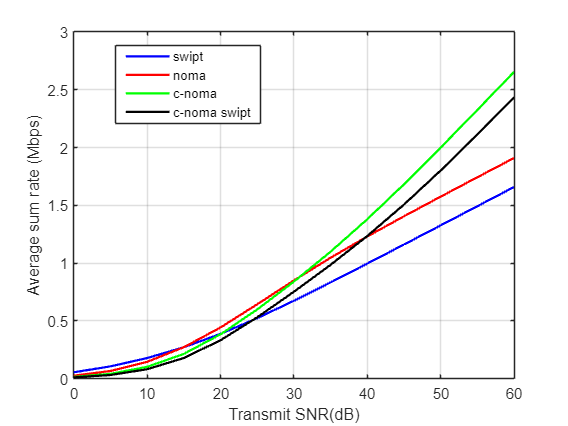

clc; clear variables; close all;

%sum rate for near user and far user with SWIPT, NOMA, C-NOMA SWIPT 
%source, 2 users. strong user acts as energy harvesting 
%relay to weak.  have direct path from BS to far user


N = 10^6;   

dsn = 1;   %Source to near user distance    
dsf = 9;   %Source to far user distance
dnf = dsf - dsn; %Near user to far user distance
eta = 2;    %Path loss exponent
%Rayleigh fading coefficients
hsn = (randn(1,N)+1i*randn(1,N))/sqrt(2) ;
gsn = ((abs(hsn)).^2);
hsf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsf = ((abs(hsf)).^2);
hnf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gnf = ((abs(hnf)).^2);



Pt = 0:5:60;    % 发送功率（dBm）
pt =  10.^(Pt/10);    % 发送功率（线性尺度）mW
B = 1000000;             %bandwidth 1 MHz
B1 = B/2;               %bandwidth for swipt oma
N0_dBm=-60;                % Noise special density  (in dBm/Hz)
N0=(10^(N0_dBm/10))*B;          % Linear noise in mW
N01 = (10^(N0_dBm/10))*B1;      %linear noise for swipt oma
snr = pt/N0;       %SNR in linear
snr1 = pt/(N01);       %SNR in linear(swipt oma)
SNR = 10*log10(snr);%SNR in dB

%Power allocation factors
af = 0.8; an = 0.2;
R1 = 0.3; %Target rate for far user
t1 = (2^(2*R1))-1;   %target snr for both users
R2 = 1;   %target rate for near user
t2 = (2^(2*R2))-1;
eff = 0.7;  %power harvesting efficiency of the near user
frac = 0.3; %power splitting coefficient
del = 10^-6; %a small number

%Some buffers
pn = zeros(1,length(pt));
pf = zeros(1,length(pt));

cn = zeros(1,length(pt));
cf = zeros(1,length(pt));
cph = zeros(1,length(pt));
rsum = zeros(1,length(pt));
csn = zeros(1,length(pt));
cfs = zeros(1,length(pt));
cnc = zeros(1,length(pt));
cfc = zeros(1,length(pt));
cfcn = zeros(1,length(pt));
cfcf = zeros(1,length(pt));
sum_s = zeros(1,length(pt));
sum_n = zeros(1,length(pt));
sum_cn = zeros(1,length(pt));


for u = 1:length(pt)    
   
    

    %Amount of power harvested by near user
    ph = pt(u)*gsn.*frac*eff/(1+dsn^eta);
    

    %SNIR for each user
    SNRnf = af*snr(u)*(1-frac).*gsn./(snr(u).*(an*(1-frac).*gsn) + (1+dsn^eta));
    SNRnf1 = af*snr(u).*gsn./(snr(u).*(an*gsn) + (1+dsn^eta));
    SNRnn = an*snr(u)*(1-frac).*gsn/(1+dsn^eta);
    SNRsf = af*snr(u).*gsf./(snr(u).*an.*gsf+1+dsf^eta);
    SNRfmrc = SNRsf + (eff*snr(u).*gnf.*frac.*gsn./((1+dsn^eta)*(1+dnf^eta)));
    sSNRn = (1-frac)*snr1(u).*gsn./(dsn^eta);   %near user, swipt SNR
    sSNRf = (1-frac)*snr1(u).*gsf./(dnf^eta);
    nSNRn = snr(u).*gsn*an./(dsn^eta);         %near user, noma
    nSNRf = snr(u).*gsf*af./(snr(u)*an*gsf+1+dsf^eta);
    cnSNRn = an*snr(u)*gsn/(1+dsn^eta);       %near user, cnoma
    cnSNRf = SNRsf + (gnf*snr(u)*an/(1+dnf^eta));%far user,cnoma

    %Achievable rate of near user
    Rnf = 0.5 *0.2*log2(1 + SNRnf);
    Rnn = 0.5 *0.2*log2(1 + SNRnn);
    Rnf1 = 0.5 * 0.2*log2(1 + SNRnf1);
    Rsn = 0.5*0.5*0.2*log2(1 + sSNRn);    %data rate for near user, swipt
    Rn_n = 0.5*0.2*log2(1 + nSNRn);    %data rate for near user, NOMA
    Rcn_n = 0.5*0.2*log2(1 + cnSNRn);  %data rate for near user, cnoma
    %Achievable rate of far user
    Rf = 0.5 *0.2*log2(1 + SNRfmrc);
    Rsf = 0.5*0.2*log2(1 + SNRsf);
    Rfs= 0.5*0.5*0.2*log2(1 + sSNRf);       %data rate for far user, swipt
    Rcf = 0.5*0.2*log2(1 + nSNRf);      %far user, NOMA
    Rcnf = 0.5*0.2*log2(1+ cnSNRf); %far user, cnoma
    


    %calculate average rate for each user and the sum rate
    cn(u) = mean(Rnn);
    cf(u) = mean(Rf);
    cph(u) = mean(ph);
    csn(u) = mean(Rsn);%swipt near
    cfs(u) = mean(Rfs);%swipt far
    cnc(u) = mean(Rn_n);%NOMA near
    cfc(u) = mean(Rcf);%NOMA far
    cfcn(u) = mean(Rcn_n);%CNOMA near
    cfcf(u) = mean(Rcnf);%CNOMA far

    rsum(u) = cn(u) + cf(u);
    sum_s(u) = csn(u) + cfs(u);%sum rate swipt
    sum_n(u) = cnc(u) + cfc(u);%sum rate noma
    sum_cn(u) = cfcn(u) + cfcf(u);%sum rate cnoma
    
    for k=1:N
       if (  Rf(k)<R1) &&(SNRnf(k)>R1)
          pf(u) = pf(u) + 1;
       end
        if (Rsf(k) < R1)&&(Rnf(k)<R1)
          pf(u) = pf(u) + 1;
        end
        if Rnf1(k)<R1 
          pn(u) = pn(u) + 1;
       end
        if (Rnf1(k) > R1)&&(Rnn(k)<R2)
          pn(u) = pn(u) + 1;
       end

    end

    
end

poutn1 = pn/N;
poutf1 = min(pf/N,1);



figure;
plot(Pt, sum_s, 'b', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
plot(Pt, sum_n, 'r', 'LineWidth', 1.5, 'MarkerSize', 6);
plot(Pt, sum_cn, 'g', 'LineWidth', 1.5, 'MarkerSize', 6);
plot(Pt, rsum, 'k', 'LineWidth', 1.5, 'MarkerSize', 6);
legend('swipt','noma','c-noma','c-noma swipt');
xlabel('Transmit SNR(dB)');
ylabel('Average sum rate (Mbps)');

legend("Position", [0.213,0.71813,0.23689,0.16969])